# Nonlinear Validation of the System and Measurements

First, bringing in the provided simulated data, and the simulation parameters as described in `OrbitDetermination-fall2023.pdf.`

% simulation parameters
load sim_setup.mat
% bringing in simulation data
load orbitdetermination-finalproj_data_2023_11_14.mat 

Please note that any variables specified in the table from the assignment are loaded in `sim_setup.m`.

Many functions were written to assist this project. All of them live below. 

addpath('./functions/')

## Nonlinear State Simulation

Looking at the state evolution with initial conditions as described in the assignment, using `ode45():`

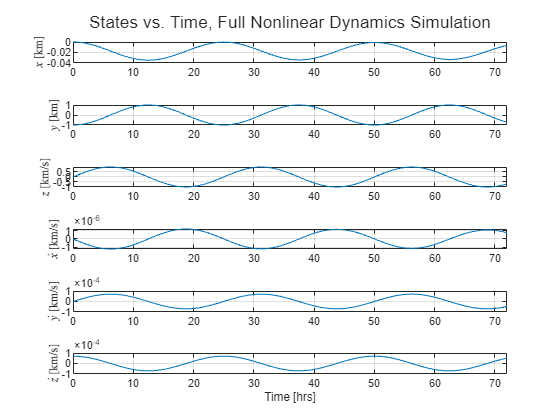

x_0 = [r_nom; dr_nom];              % Initial conditions
n = length(x_0');                   % number of state variables
t_obs = unique(y_table(:, 1));      % Times of interest, where there are observations 

% Solving the ODE with ICs and times of interest
options = odeset('RelTol',1e-12);
[~,x_ode45] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), t_obs, x_0, options);

% plotting non-linear simulation solution
figure;
fig = tiledlayout(n,1);
ylabels = ["$x$ [km]", "$y$ [km]","$z$ [km/s]","$\dot x$ [km/s]", "$\dot y$ [km/s]","$\dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    plot(t_obs/60/60,x_ode45(:,i))
    xlim([t_obs(1)/60/60, t_obs(end)/60/60])
    ylabel(ylabels(i),Interpreter='latex')
    grid on
end
xlabel("Time [hrs]")
title(fig,"States vs. Time, Full Nonlinear Dynamics Simulation")

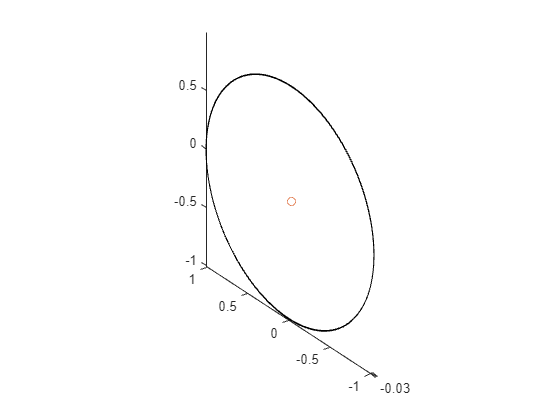


% Plotting SC in asteroid-centered, asteroid-intertial frame
figure;
plot3(x_ode45(:,1),x_ode45(:,2),x_ode45(:,3),'black',0,0,0,'o',)
axis equal